clear; clc; close all

% Riproducibilità
rng(42);

% Immagini
path = fullfile('Dataset', 'Da usare');
imgs = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Immagini
path2 = fullfile('Dataset', 'Da usare1');
imgs2 = imageDatastore(path2, "IncludeSubfolders", true, "LabelSource", "foldernames");

# EDA

fprintf('Numero totale di immagini: %d\n', numel(imgs.Labels));

Numero totale di immagini: 60000


fprintf('Training: %d\n', numel(imgs.Labels) * 0.7);

Training: 42000


fprintf('Validazione: %d\n', numel(imgs.Labels) * 0.15);

Validazione: 9000


fprintf('Test: %d\n\n', numel(imgs.Labels) * 0.15);

Test: 9000



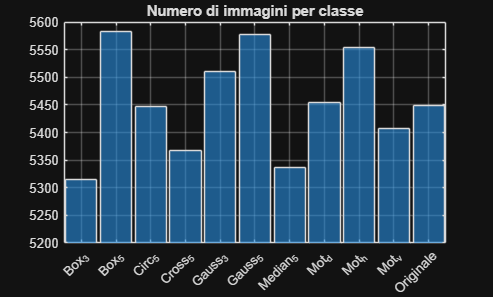


% Immagini per classe
figure;

countcats(imgs.Labels);
histogram(imgs.Labels);

title('Numero di immagini per classe');
ylim([5200, 5600]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

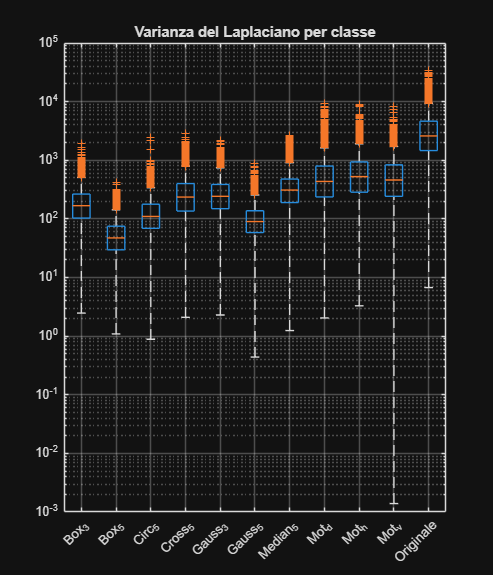



% Boxplot del laplaciano per classe
figure;

T = readtable(fullfile(path, 'blur_scores.csv'), ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

T.kernel = categorical(T.kernel);
T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));

boxplot(T.blur_score_dopo, T.kernel);
set(gcf, 'Position', [100, 100, 600, 700]);

set(gca,'YScale', 'log')

ax = gca;
ax.TickLabelInterpreter = 'tex';

title('Varianza del Laplaciano per classe');

xtickangle(45);
grid on;


fprintf(['L''asse delle ordinate usa la scala logaritmica a causa dell''enorme\n' ...
    'differenza tra i valori della classe "Originale" e tutte le altre']);

L'asse delle ordinate usa la scala logaritmica a causa dell'enorme
differenza tra i valori della classe "Originale" e tutte le altre



fprintf('%s\n', repmat(' ', 1, 80));

% Altro dataset

fprintf('Secondo test:\n');

Secondo test:


fprintf('Numero totale di immagini: %d\n', numel(imgs2.Labels));

Numero totale di immagini: 1360


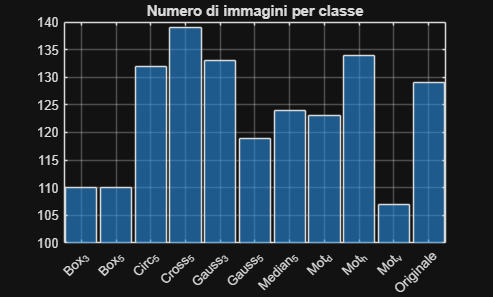


% Immagini per classe
figure;

countcats(imgs2.Labels);
histogram(imgs2.Labels);

title('Numero di immagini per classe');
ylim([100, 140]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

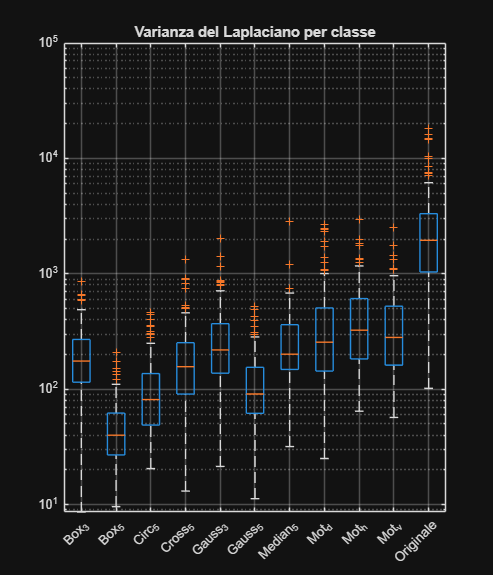



% Boxplot del laplaciano per classe
figure;

T = readtable(fullfile(path2, 'blur_scores.csv'), ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

T.kernel = categorical(T.kernel);
T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));

boxplot(T.blur_score_dopo, T.kernel);

set(gcf, 'Position', [100, 100, 600, 700]);

set(gca,'YScale', 'log')

ax = gca;
ax.TickLabelInterpreter = 'tex';

title('Varianza del Laplaciano per classe');

xtickangle(45);
grid on;


fprintf('Stesso discorso anche qui, i valori sono tuttavia più sparsi');

Stesso discorso anche qui, i valori sono tuttavia più sparsi

# Test accuratezza

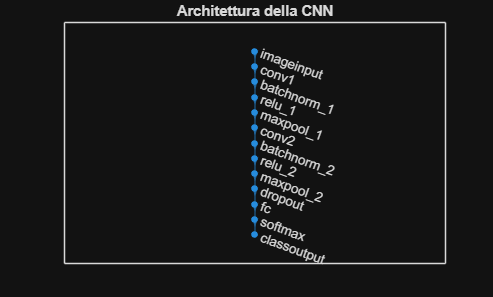

% Servono solo quelle di test
[~ , imgsTemp] = splitEachLabel(imgs, 0.7, "randomized");
[~, imgsTest] = splitEachLabel(imgsTemp, 0.5, "randomized");

% Carica la cnn addestrata
S = load('rete1.mat');

% Mostra struttura
lgraph = layerGraph(S.layers);
figure;
plot(lgraph)
title('Architettura della CNN');

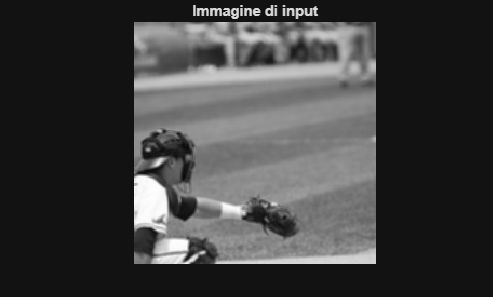


% Mostra attivazioni
I = readimage(imgsTest, 1);

figure
imshow(I)
title('Immagine di input')

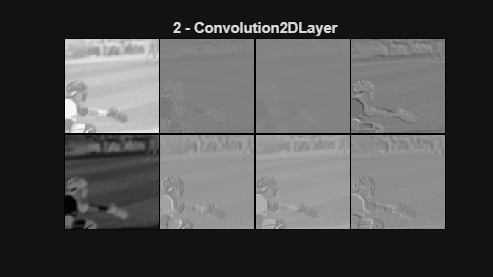

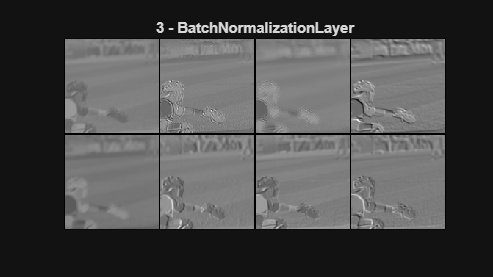

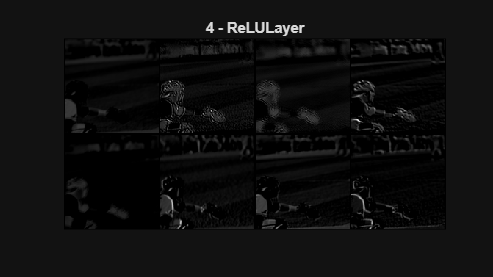

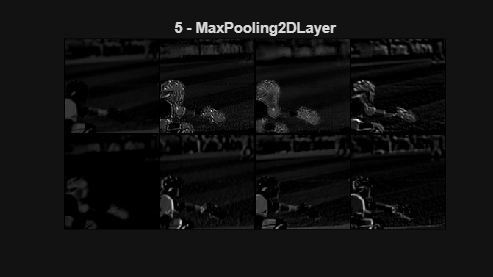

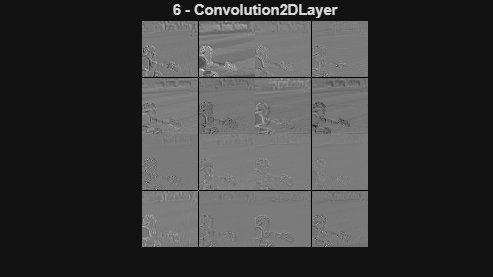

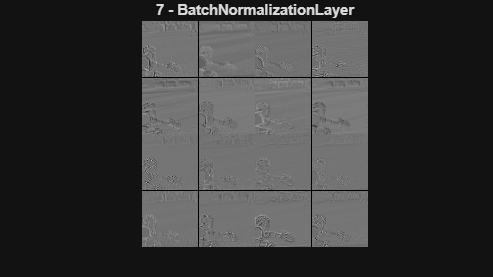

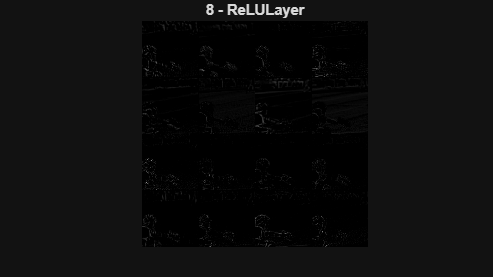

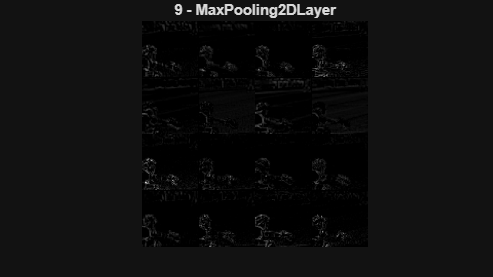


for i = 1:numel(S.net.Layers)

    try
        A = activations(S.net, I, i, 'OutputAs', 'channels');

        if ndims(A)==3

            figure('Units', 'normalized', 'OuterPosition', [0 0 1 1])
            montage(mat2gray(A), ...
                    'Size', [NaN 4], ...
                    'ThumbnailSize', [128 128], ...
                    'BorderSize', [1 1]);
            title(sprintf('%d - %s', ...
                i, erase(class(S.net.Layers(i)), 'nnet.cnn.layer.')))

        end

    catch
    end

end

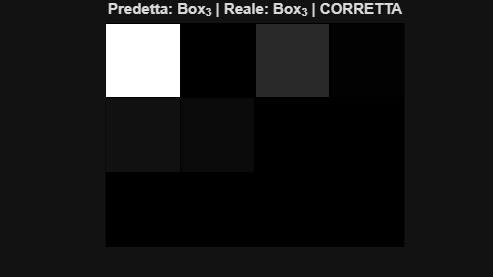


% Predizione della rete
YPred = classify(S.net, I);

% Etichetta reale
YTrue = imgsTest.Labels(1);

% Confronto
if YPred == YTrue
    risultato = 'CORRETTA';
else
    risultato = 'ERRATA';
end

title(sprintf('Predetta: %s | Reale: %s | %s', ...
    string(YPred), string(YTrue), risultato))

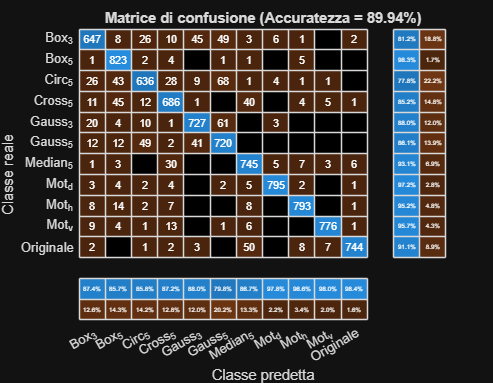



% Matrice di confusione
YPred = classify(S.net, imgsTest);
YTest = imgsTest.Labels;

accuracy = mean(YPred == YTest);

figure('Position', [100 100 900 700]);
cm = confusionchart(YTest, YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Classe predetta';
cm.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione (Accuratezza = %.2f%%)', accuracy * 100));

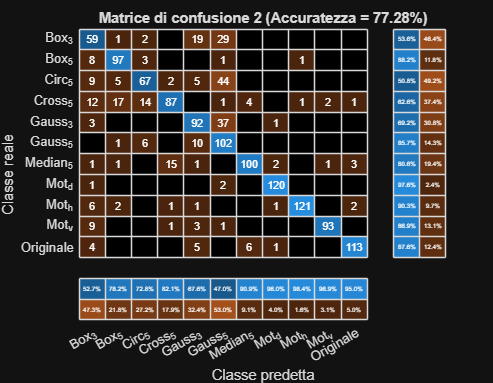


% Secondo dataset
YPred2 = classify(S.net, imgs2);
YTest2 = imgs2.Labels;

accuracy2 = mean(YPred2 == YTest2);

figure('Position', [100 100 900 700]);
cm2 = confusionchart(YTest2, YPred2);
cm2.RowSummary = 'row-normalized';
cm2.ColumnSummary = 'column-normalized';
cm2.XLabel = 'Classe predetta';
cm2.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione 2 (Accuratezza = %.2f%%)', accuracy2 * 100));